# Google 評論爬蟲 Google Comments Crawler

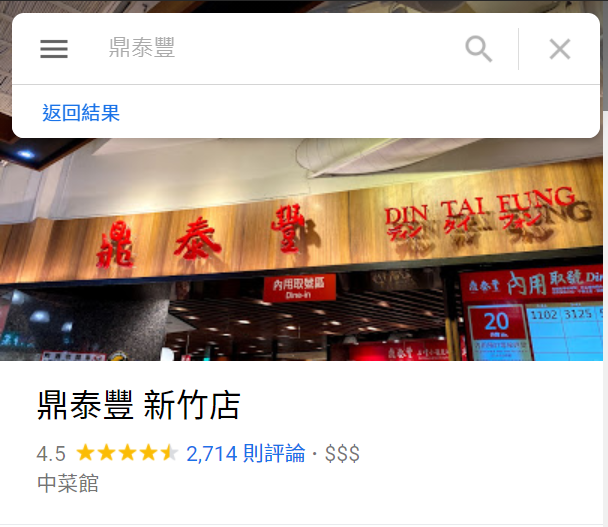

## 爬取店家評論內容與評論星級

searchToken = '鼎泰豐';
searchTerm = urlencode(searchToken);
fprintf('搜尋關鍵字為: %s\n',searchToken)

搜尋關鍵字為: 鼎泰豐


## 獲取使用者位置 (From Google Map)

[latitude,longitude] = getUserLocation;

現在位置為: 24.8119296°N, 121.0384384°E


## 爬取網址參數設定

searchURL = ['https://www.google.com.tw/search?tbm=map&authuser=0&hl=zh-TW&gl=tw&pb=!4m9!1m3!1d1858071.018126',...
    '!2d',longitude,...
    '!3d',latitude,...
    '!2m0!3m2!1i406!2i762!4f13.1!7i20!10b1!12m8!1m1!18b1!2m3!5m1!6e2!20e3!10b1!16b1!19m4!2m3!1i360!2i120!4i8!20m65!2m2!1i203!2i100!3m2!2i4!5b1!6m6!1m2!1i86!2i86!1m2!1i408!2i240!7m50!1m3!1e1!2b0!3e3!1m3!1e2!2b1!3e2!1m3!1e2!2b0!3e3!1m3!1e3!2b0!3e3!1m3!1e8!2b0!3e3!1m3!1e3!2b1!3e2!1m3!1e10!2b0!3e3!1m3!1e10!2b1!3e2!1m3!1e9!2b1!3e2!1m3!1e10!2b0!3e3!1m3!1e10!2b1!3e2!1m3!1e10!2b0!3e4!2b1!4b1!9b0!22m6!1sBrqTYIG1CLLTmAXT-azADw%3A2!2s1i%3A0%2Ct%3A11886%2Cp%3ABrqTYIG1CLLTmAXT-azADw%3A2!7e81!12e5!17sBrqTYIG1CLLTmAXT-azADw%3A76!18e15!24m54!1m16!13m7!2b1!3b1!4b1!6i1!8b1!9b1!20b1!18m7!3b1!4b1!5b1!6b1!9b1!13b1!14b0!2b1!5m5!2b1!3b1!5b1!6b1!7b1!10m1!8e3!14m1!3b1!17b1!20m2!1e3!1e6!24b1!25b1!26b1!29b1!30m1!2b1!36b1!43b1!52b1!54m1!1b1!55b1!56m2!1b1!3b1!65m5!3m4!1m3!1m2!1i224!2i298!89b1!26m4!2m3!1i80!2i92!4i8!30m0!34m17!2b1!3b1!4b1!6b1!8m5!1b1!3b1!4b1!5b1!6b1!9b1!12b1!14b1!20b1!23b1!25b1!26b1!37m1!1e81!42b1!47m0!49m1!3b1!50m4!2e2!3m2!1b1!3b1!65m1!1b1!67m2!7b1!10b1!69i556',...
    '&q=',searchTerm,...
    '&oq=',searchTerm,...
    '&gs_l=maps.3..38i39i111i426k1.127976.137501.1.143238.20.20.0.0.0.0.315.1499.8j3j1j1.17.0....0...1ac.1j4.64.maps..3.17.2417.2..38i39k1j38i426k1j38i376k1j115i144k1j38i442i426k1j38i72k1.12.&tch=1&ech=1&psi=BrqTYIG1CLLTmAXT-azADw.1620294152153.1'];
opt = weboptions('ContentType','text');
rawMapInfo = webread(searchURL,opt);
rawMapInfo = regexprep(rawMapInfo,'\/\*""\*\/','');
MapInfo = jsondecode(rawMapInfo);

## 處理搜尋條件例外

commentRaw = MapInfo.d;
rawData_search = regexprep(commentRaw,")]}\'",'');
jsonData_search = jsondecode(rawData_search);
if length(jsonData_search{1}{2}{1})<15
    % 如果搜尋為關鍵字，選擇相關性第一之店家
    storeCode = jsonData_search{1}{2}{2}{15}{73}{1}{1}{30};
    storeChosen = jsonData_search{1}{2}{2}{15}{12};
    fprintf('搜尋為關鍵字，選擇最相關之結果爬取: %s\n',storeChosen)
else
    storeCode = jsonData_search{1}{2}{1}{15}{73}{1}{1}{30};
    storeChosen = jsonData_search{1}{2}{1}{15}{12};
    fprintf('爬取搜尋內容: %s\n',storeChosen)
end

搜尋為關鍵字，選擇最相關之結果爬取: 鼎泰豐 新竹店


## 爬取資料

commentResult = [];
disp('****開始爬取****')

****開始爬取****


for i = 0:10:100 % 10 comments per page
    % Wait for page load
    %     pause(0.5)
    section = num2str(i);
    fprintf('爬取第%.0f-%.0f篇貼文\n',i,i+10)
    commentURL = ['https://www.google.com/maps/preview/review/listentitiesreviews?authuser=0&hl=zh-TW&gl=tw&pb=!1m2',...
        '!1y',storeCode{1},...
        '!2y',storeCode{2},...
        '!2m2!1i',...
        section,...
        '!2i10!3e1!4m5!3b1!4b1!5b1!6b1!7b1!5m2!1s_52TYKO3CNDr-QaSwqvYDQ!7e81'];
    rawData = webread(commentURL,opt);
    rawData = regexprep(rawData,")]}\'",'');
    jsonData = jsondecode(rawData);

    extractData = jsonData{3};
    if isempty(extractData)
        disp('程序中止-沒有更多評論')
        break
    end
    if iscell(extractData)
        commentInfo = cellfun(@DataFormatting,extractData,'UniformOutput',false);
        tempResult = vertcat(commentInfo{:});
        commentResult = [commentResult;tempResult];
    end
end

爬取第0-10篇貼文
爬取第10-20篇貼文
爬取第20-30篇貼文
爬取第30-40篇貼文
爬取第40-50篇貼文
爬取第50-60篇貼文
爬取第60-70篇貼文
爬取第70-80篇貼文
爬取第80-90篇貼文
爬取第90-100篇貼文
爬取第100-110篇貼文


disp('****爬取結束****')

****爬取結束****


## 顯示爬取結果

if ~isempty(commentResult)
    fprintf('爬取成功! 共爬取%.0f篇貼文\n',height(commentResult))
else
    disp('爬取失敗')
end

爬取成功! 共爬取110篇貼文


head(commentResult)

ans = 8×4 table
        username             day                                                                                                                                                                                                                                                                                                                                                                                                       comment                                                                                                                                                                                                                                                                                                                                                                                                   rate
    _________________    ___________    ____________

## Helper Function

function info = DataFormatting(raw)
info.username = '';
info.day = '';
info.comment = '';
info.rate = '';

if ~isempty(raw{1}{2})
    info.username = raw{1}{2};
end

if ~isempty(raw{2})
    info.day = raw{2};
end

if ~isempty(raw{4})
    info.comment = raw{4};
end

if ~isempty(raw{5})
    info.rate = raw{5};
end
info = struct2table(info,'AsArray',true);
end

function [latitude,longitude] = getUserLocation
locationURL = 'https://www.google.com.tw/maps';
output = webread(locationURL);
locationInfo = unique(regexp(output,'(center=.*?&amp?)','match'));
location = regexp(locationInfo,'(\d*\.\d*)','match');
latitude = location{1}{1};
longitude = location{1}{2};


if str2double(latitude) >= 0
    lat_postfix = '°N';
else
    lat_postfix = '°S';
end
if str2double(longitude) >= 0
    long_postfix = '°E';
else
    long_postfix = '°W';
end

fprintf('現在位置為: %s%s, %s%s\n',latitude,lat_postfix,longitude,long_postfix)
end